%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% TUE 5SMB0 System Identification
%%% Assignment 2022
%%% Authors: Jiaxuan Zhang, Yiting Li
%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Data Generation

% [ u , y ] = assignment_sys_36(r)



## Part 1: Understanding Saturation and Butterworth Filter

### 1.1

F.num = [ 0.505 , 1.01 , 0.505 ];
F.denom = [ 1 , 0.7478 , 0.2722 ];
F.sys = tf(F.num, F.denom, -1, 'Variable', 'z^-1');
F.sys

ans =
 
  0.505 + 1.01 z^-1 + 0.505 z^-2
  ------------------------------
  1 + 0.7478 z^-1 + 0.2722 z^-2
 
Sample time: unspecified
Discrete-time transfer function.



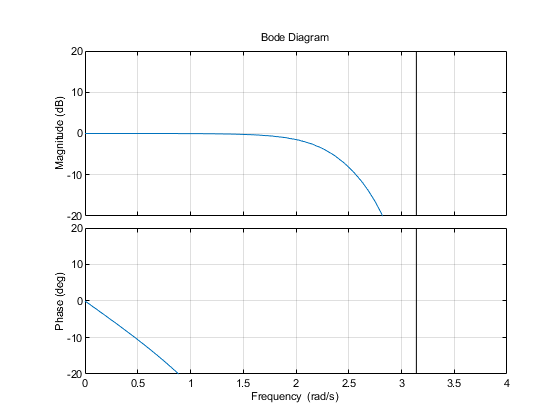

plotopts1 = bodeoptions;
plotopts1.FreqScale = 'linear';
plotopts1.XLim = {[0,4]};
plotopts1. Ylim = {[-20,20]};
plotopts1.Grid = 'on';
bode(F.sys, plotopts1)

% 2.195 is the -3 db point, approximately 0.6990 pi


### 1.2

nu = 100;
previous_u = -100; 
for mag=0:1:100
    r = mag * ones(1,nu);
    [u,y] = assignment_sys_36(r);
    u(1)
    previous_u
    if (u(1) == previous_u)
        fprintf("M is equal to %d", u(1));
        break;
    end
    previous_u = u(1);
end

ans = 0

previous_u = -100

ans = 0.5050

previous_u = 0

ans = 1.0100

previous_u = 0.5050

ans = 1.5150

previous_u = 1.0100

ans = 2.0200

previous_u = 1.5150

ans = 2.5250

previous_u = 2.0200

ans = 3

previous_u = 2.5250

ans = 3

previous_u = 3

M is equal to 3


% M is equal to 3


## Part 2: Nonparametric identification

### 2.1 

period = 128;
N = 1024;
r = 3*sin( [0: 1: N-1] * pi / period )

r =          0    0.0736    0.1472    0.2207    0.2941    0.3672    0.4402    0.5129    0.5853    0.6573    0.7289    0.8001    0.8709    0.9410    1.0107    1.0797    1.1481    1.2157    1.2827    1.3488    1.4142    1.4787    1.5423    1.6050    1.6667    1.7274    1.7871    1.8457    1.9032    1.9595    2.0147    2.0686    2.1213    2.1727    2.2229    2.2716    2.3190    2.3650    2.4096    2.4528    2.4944    2.5346    2.5732    2.6103    2.6458    2.6797    2.7120    2.7426    2.7716    2.7990


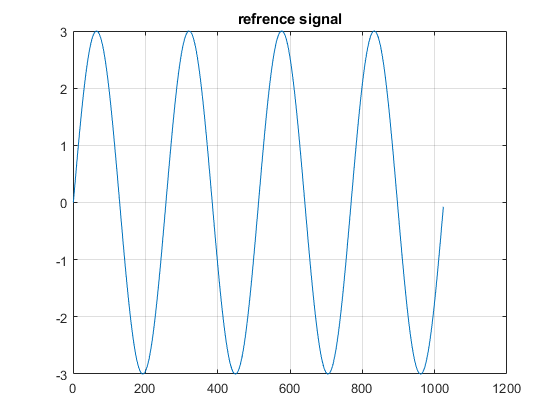

plot(r)
grid on
title('refrence signal')

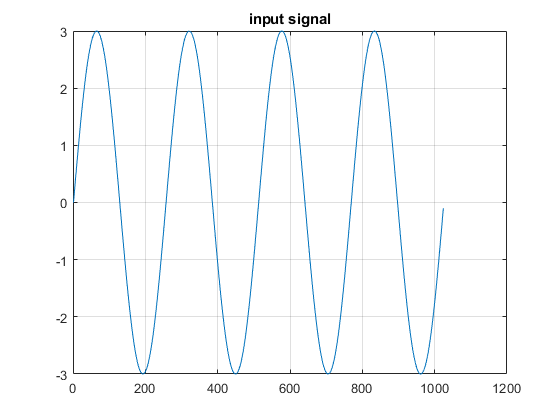

[u,y] = assignment_sys_36(r);
plot(u)
grid on
title('input signal')

G_ETFE = etfe(iddata(y,u))

G_ETFE =
IDFRD model.
Contains Frequency Response Data for 1 output(s) and 1 input(s).
Response data is available at 128 frequency points, ranging from 0.02454 rad/s to 3.142 rad/s.
 
Sample time: 1 seconds
Output channels: 'y1'
Input channels: 'u1'
Status:                                  
Estimated using ETFE on time domain data.


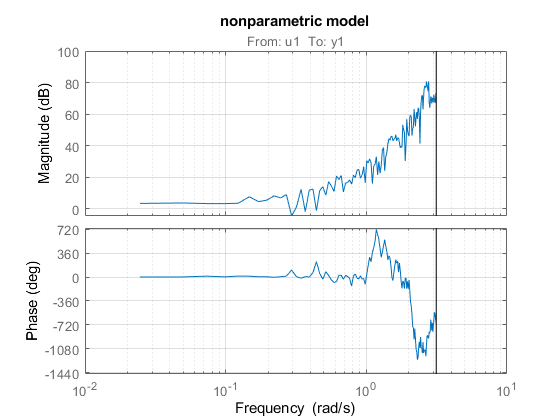

bode(G_ETFE)
grid on
title ('nonparametric model')

### 2.3

period = 128;
N = 1024;
r = 0*sin( [0: 1: N-1] * pi / period )

r =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


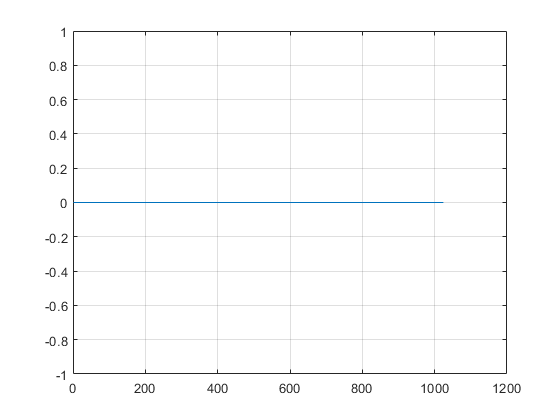

plot(r)
grid on

[u,y] = assignment_sys_36(r);
plot(u)
grid on

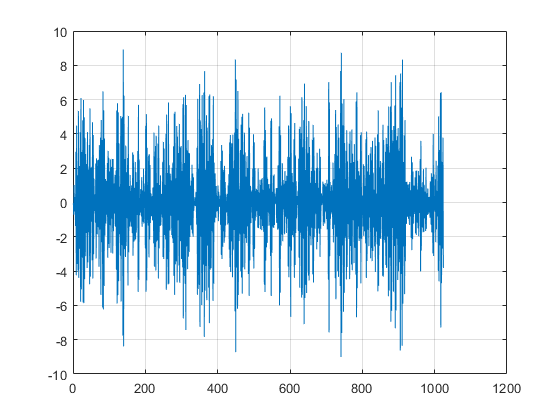

plot(y)
grid on

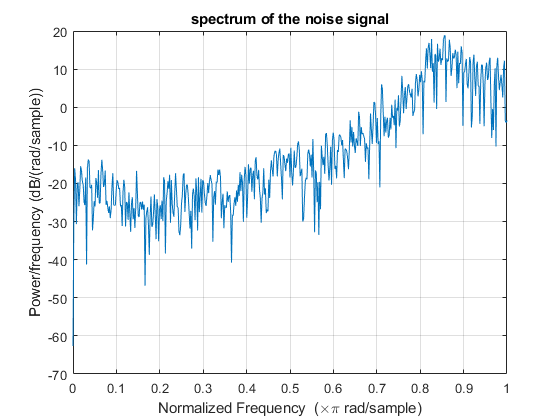

[Pv, W] = cpsd(y,y,1024);
cpsd(y,y,1024)
title('spectrum of the noise signal')

## Part 3: Expreiment Design

### 3.1

% prefer PRBS

### 3.2

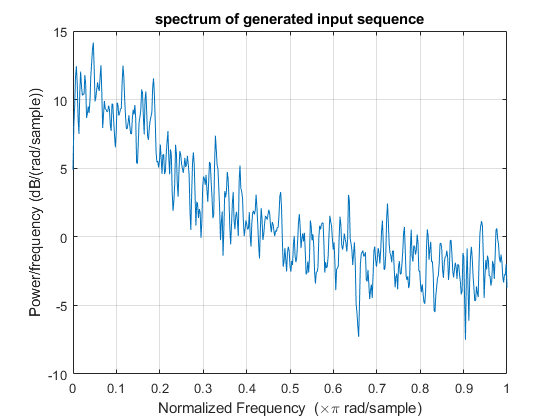

[u,P,w] = Generate_PRBS(0.83, 3000, 3, true);


% I think 0.83 is a good threshold


## Part 4: Parametric identification and validation

### 4.1

## Part 5: Experimental verification of variance estimates

### 5.1

### 5.2

### 5.3

### 5.4

## Function Used

function [u,P,w] = Generate_PRBS(probability, N, mag, plt_flag)
%%%%%%%%%%%%%%%
%% generate PRBS based on:
%% u(t) = u(t-1) with probability p
%% u(t) = -u(t-1) with probability 1-p
%% and may plot spectral density based on setting
%% input: 
%%    P : prbability
%%    N : total input points
%%    mag: output magnitude
%%    plt_flg: if true, plot sepctral density
%% output:
%%    u : generated input sequence
%%    P : spectral density of P
%%    w : spectral density points
%%%%%%%%%%%%%%%%


    % determine the initial entry of u, that is u(1)
    if rand(1,1)>=0.5
        u(1) = mag;
    else
        u(1) = -mag;
    end
    
    % generate sequence
    for i = 2:1:N
        if rand(1,1) <= probability
            u(i) = u(i-1);
        else
            u(i) = -u(i-1);
        end
    end
    
    % get spectrum of generated input sequence
    [P,w] = cpsd(u,u,N);
    
    if (plt_flag == true)
        cpsd(u, u);
        title('spectrum of generated input sequence')
    end
    
end